# Gravity Wave Hodograph

The current work flow to use this code is.

- run the setup section making sure you have selected the correct directory and sonde

- delect the altitude range of intrest with the sliders the plot will update automaticly 

- save the data if the selecterd data is desirable

- move on to the next file

- repeate steps 2-4 un till the end of the data set.

## Set up

  % only click this when you first run the script. 
clearvars
clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% select the data directory and what kind of sonde you are using
d = '.\eclipseData';
sonde = 1;
% if using DFM-17 set sonde = 1
% if using RS92 set sonde = 2
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

i = 1
if sonde == 2
t = fullfile(d, "*.csv");
files = dir(t);
else
t = fullfile(d, "*.txt");
files = dir(t);
end
current = files(i).name;
current = fullfile(d, current);
if sonde == 2
    data = readRS92Data(current);
else
    data = readRadioSondeData(current);
end
[~, idx] = max(data.Alt);
data = data(1:idx, :);
data = data(data.Alt > 12000, :);
if isempty(data)
    warning("No data above 12000m");
end
if sonde == 2
    RS = 5;
else
    RS = mean(data.Rs);
end
u = -(data.Ws) .* sind(data.Wd); % from MetPy
v = -(data.Ws) .* cosd(data.Wd); %    
[Alt, u, v, temp, bvFreqSquared] = ... 
preprocessDataNoResample(data.Alt, u, v, data.T, data.P, RS);

## Data Range Selection

figure(1)
clf
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Select the upper and lower altitude to visulize 
wl = 21800; % min
lower = find(data.Alt>=wl,1,'first');
wu = 22900; % max
upper = find(data.Alt>=wu,1,'first');
disp(files(i).name)

08202017C1_Center_Blaunch_Acer_174508.txt


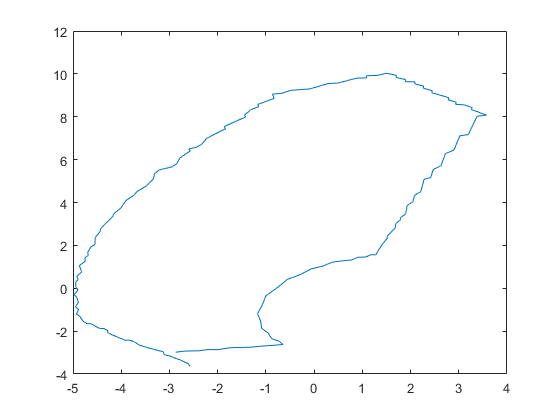

plot(u(lower:upper),v(lower:upper))

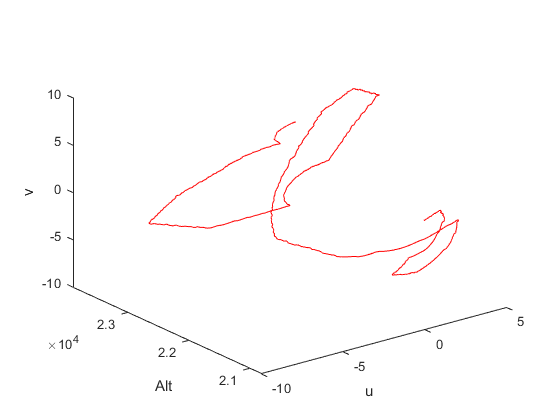

% figure(2)
% clf
% plot3(u,data.Alt,v,'r');
% ylim([wl-1000 wu+1000])
% zlabel('v'); ylabel('Alt'); xlabel('u');

## Save Data


  % click here to save the data

fprintf("%d, %d\n", Alt(lower), Alt(upper));

21800, 22902


T = table(Alt(lower:upper), u(lower:upper), v(lower:upper), temp(lower:upper), bvFreqSquared(lower:upper));
T.Properties.VariableNames = {'Alt' 'u' 'v' 'temp' 'bv2'};
[~, n, ~] = fileparts(files(i).name);
fname = sprintf(".\\hodograph\\%03u_%s-%d-%d.txt",i, n, Alt(lower), Alt(upper));
writetable(T, fname);



## Move back to the previous data file

 
i = i-1

## Move on to next data file

 
i = i+1
if i > size(files)
    warning("END of flight data");
end
